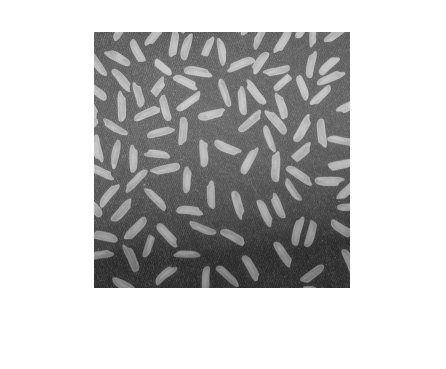

clear; clc;
rice = imread('rice.png');
figure; imshow(rice)

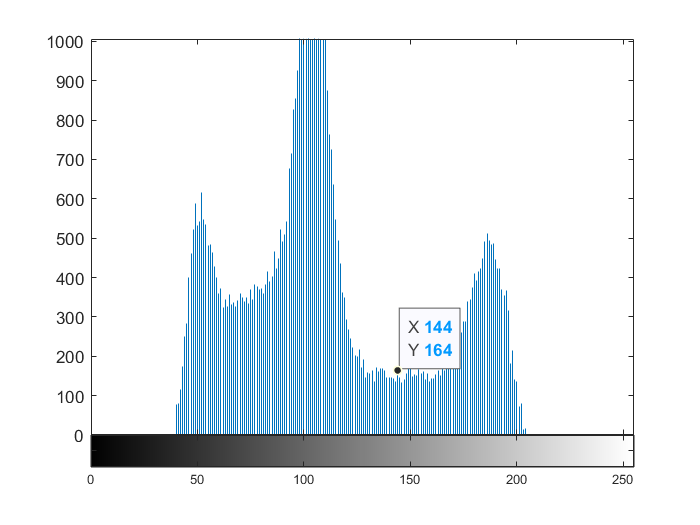

figure; imhist(rice)

## handi-threshold

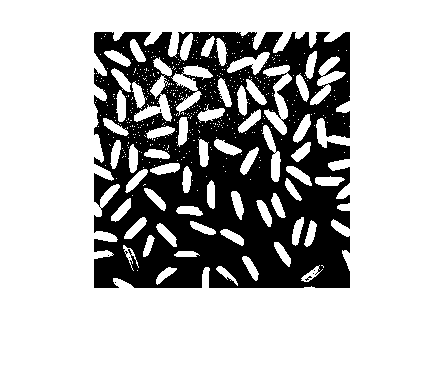

t1= 120;
rice_t1 = im2bw(rice, t1/255);
figure; imshow(rice_t1)

## otsu threshold

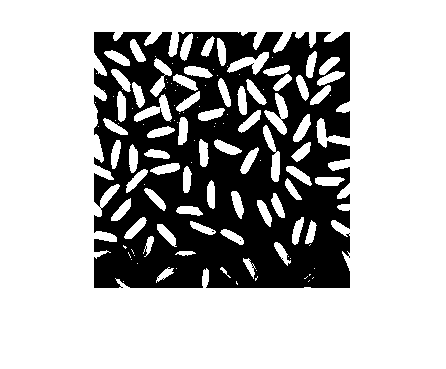

t2 = graythresh(rice);
rice_t2 = im2bw(rice, t2);
figure; imshow(rice_t2)

## adaptive threshold

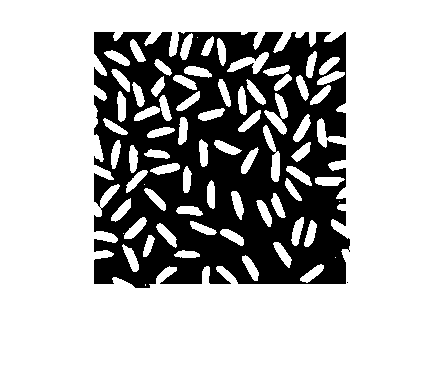

rice_t3 = blkproc(rice, [28, 28], @adaptt);        %block precedure
figure; imshow(rice_t3)

## polynomial fitting

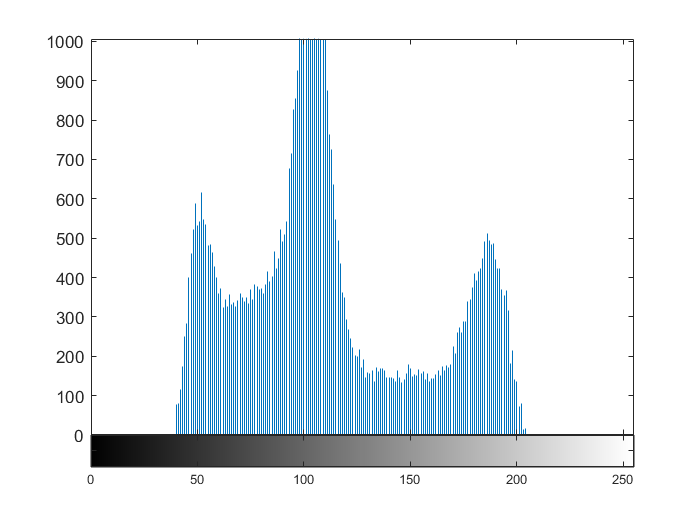

clear; clc;
rice = imread('rice.png');
figure; imhist(rice);

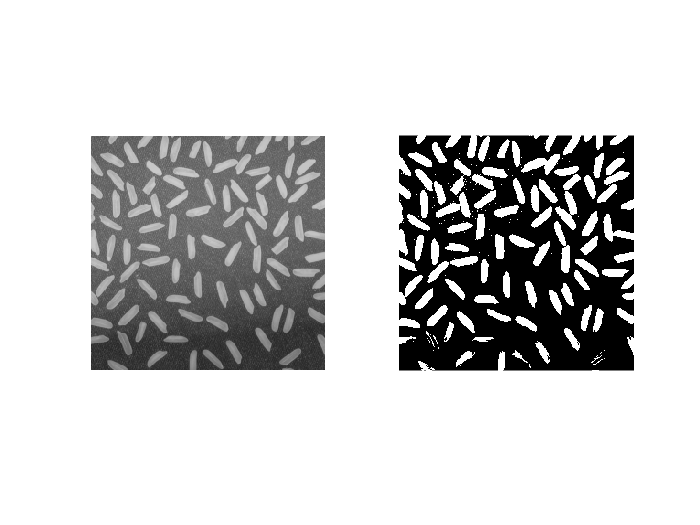

figure;
subplot(1, 2, 1); imshow(rice)
subplot(1, 2, 2); im2bw(rice, 0.5);

[counts, x] = imhist(rice);
p = polyfit(x, counts, 5);
y = polyval(p, x);

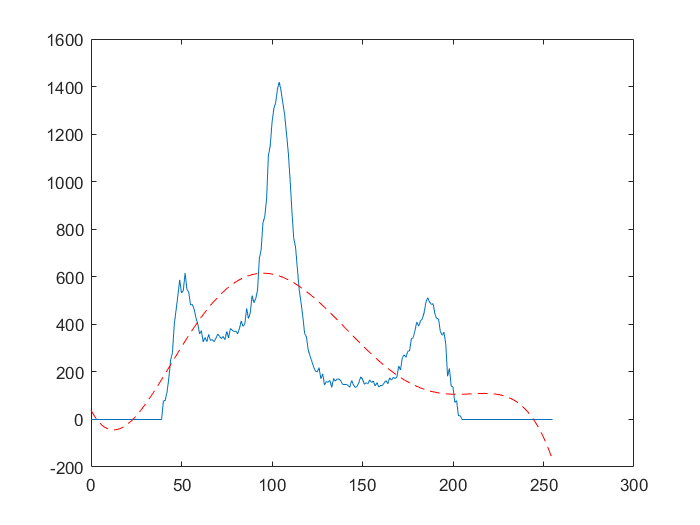

figure;
plot(x, counts)
hold on
plot(x, y, 'r--')

[firstd, ind] = sort(abs(diff(y)));       % difference between 2 
length(firstd)

ans = 255

secondd = diff(firstd);             % 2nd difference
length(secondd)

ans = 254

[value, i] = sort(secondd);
ind(i(:))

ans =    176
    45
    43
   157
   205
   141
   172
   224
   104
    42


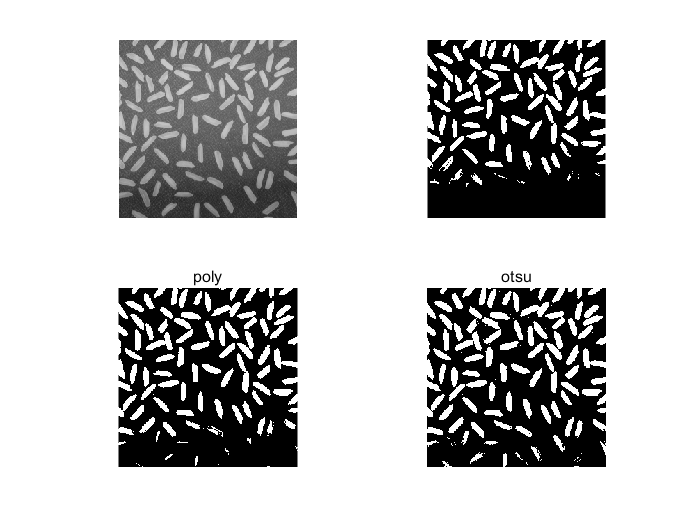

thresh = ind(i(6))/255;
figure;
subplot(2, 2, 1); imshow(rice)
subplot(2, 2, 2); im2bw(rice, 0.6);
subplot(2, 2, 3); im2bw(rice, thresh); title('poly')
level = graythresh(rice);
subplot(2, 2, 4); im2bw(rice, level); title('otsu')